# **Modulation Classification with Deep Learning**

clear all
clc

SNR = 30;
modulationTypes = categorical(["BPSK", "QPSK", "8PSK", ...
  "16QAM", "64QAM", "PAM4", "GFSK", "CPFSK", ...
  "B-FM", "DSB-AM", "SSB-AM"]);

## **Waveform Generation for Training**

numFramesPerModType = 10000;
percentTrainingSamples = 80;
percentValidationSamples = 10;
percentTestSamples = 10;

sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
fs = 200e3;             % Sample rate
fc = [902e6 100e6];     % Center frequencies

**Clock Offset**

maxDeltaOff = 5;
deltaOff = (rand()*2*maxDeltaOff) - maxDeltaOff;
C = 1 + (deltaOff/1e6);

channel = helperModClassTestChannel(...
  'SampleRate', fs, ...
  'SNR', SNR, ...
  'PathDelays', [0 1.8 3.4] / fs, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4, ...
  'MaximumClockOffset', 5, ...
  'CenterFrequency', 902e6)

channel =   helperModClassTestChannel with properties:

                    SNR: 30
        CenterFrequency: 902000000
             SampleRate: 200000
             PathDelays: [0 9.0000e-06 1.7000e-05]
       AveragePathGains: [0 -2 -10]
                KFactor: 4
    MaximumDopplerShift: 4
     MaximumClockOffset: 5


% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(1235)
tic

numModulationTypes = length(modulationTypes);

channelInfo = info(channel);
transDelay = 50;
dataDirectory = fullfile(tempdir,"ModClassDataFiles");
disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\User\AppData\Local\Temp\ModClassDataFiles


fileNameRoot = "frame";

% Check if data files exist
dataFilesExist = false;
if exist(dataDirectory,'dir')
  files = ls(fullfile(dataDirectory,sprintf("%s*",fileNameRoot)));
  if length(files) == numModulationTypes*numFramesPerModType
    dataFilesExist = true;
  end
end

if ~dataFilesExist
  disp("Generating data and saving in data files...")
  [success,msg,msgID] = mkdir(dataDirectory);
  if ~success
    error(msgID,msg)
  end
  for modType = 1:numModulationTypes
    fprintf('%s - Generating %s frames\n', ...
      datestr(toc/86400,'HH:MM:SS'), modulationTypes(modType))
    
    label = modulationTypes(modType);
    numSymbols = (numFramesPerModType / sps);
    dataSrc = helperModClassGetSource(modulationTypes(modType), sps, 2*spf, fs);
    modulator = helperModClassGetModulator(modulationTypes(modType), sps, fs);
    if contains(char(modulationTypes(modType)), {'B-FM','DSB-AM','SSB-AM'})
      % Analog modulation types use a center frequency of 100 MHz
      channel.CenterFrequency = 100e6;
    else
      % Digital modulation types use a center frequency of 902 MHz
      channel.CenterFrequency = 902e6;
    end
    
    for p=1:numFramesPerModType
      % Generate random data
      x = dataSrc();
      
      % Modulate
      y = modulator(x);
      
      % Pass through independent channels
      rxSamples = channel(y);
      
      % Remove transients from the beginning, trim to size, and normalize
      frame = helperModClassFrameGenerator(rxSamples, spf, spf, transDelay, sps);
      
      % Save data file
      fileName = fullfile(dataDirectory,...
        sprintf("%s%s%03d",fileNameRoot,modulationTypes(modType),p));
      save(fileName,"frame","label")
    end
  end
else
  disp("Data files exist. Skip data generation.")
end

Data files exist. Skip data generation.


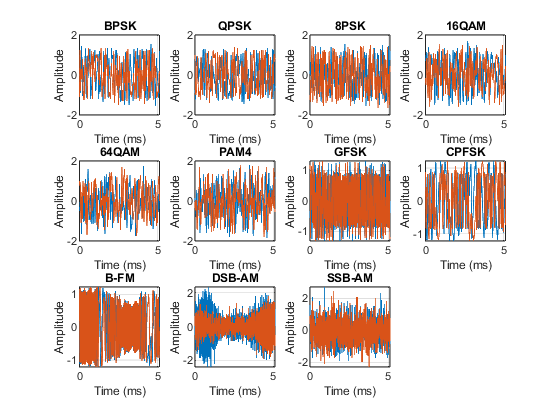

% Plot the amplitude of the real and imaginary parts of the example frames
% against the sample number
helperModClassPlotTimeDomain(dataDirectory,modulationTypes,fs)

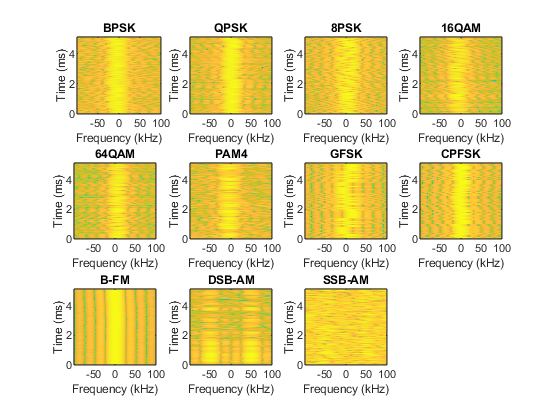

% Plot the spectrogram of the example frames
helperModClassPlotSpectrogram(dataDirectory,modulationTypes,fs,sps)

**Create a Datastore**

frameDS = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);

**Transform Complex Signals to Real Arrays**

frameDSTrans = transform(frameDS,@helperModClassIQAsPages);

**Split into Training, Validation, and Test**

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTrans,validDSTrans,testDSTrans] = helperModClassSplitData(frameDSTrans,splitPercentages);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).
Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 1 min 1 sec
- Pass 2 of 2: Completed in 1 min 30 sec
Evaluation completed in 2 min 33 sec


**Import Data Into Memory**

% Gather the training and validation frames into the memory
trainFramesTall = tall(transform(trainDSTrans, @helperModClassReadFrame));
rxTrainFrames = gather(trainFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 49 sec
Evaluation completed in 50 sec


rxTrainFrames = cat(4, rxTrainFrames{:});
validFramesTall = tall(transform(validDSTrans, @helperModClassReadFrame));
rxValidFrames = gather(validFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 13 sec
Evaluation completed in 13 sec


rxValidFrames = cat(4, rxValidFrames{:});

% Gather the training and validation labels into the memory
trainLabelsTall = tall(transform(trainDSTrans, @helperModClassReadLabel));
rxTrainLabels = gather(trainLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 35 sec
- Pass 2 of 2: Completed in 1 min 4 sec
Evaluation completed in 1 min 40 sec


validLabelsTall = tall(transform(validDSTrans, @helperModClassReadLabel));
rxValidLabels = gather(validLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 12 sec
- Pass 2 of 2: Completed in 14 sec
Evaluation completed in 27 sec


## **Train the CNN**

modClassNet = helperModClassCNN(modulationTypes,sps,spf);

maxEpochs = 12;
miniBatchSize = 256;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels);

  fprintf('%s - Training the network\n', datestr(toc/86400,'HH:MM:SS'))

00:12:36 - Training the network


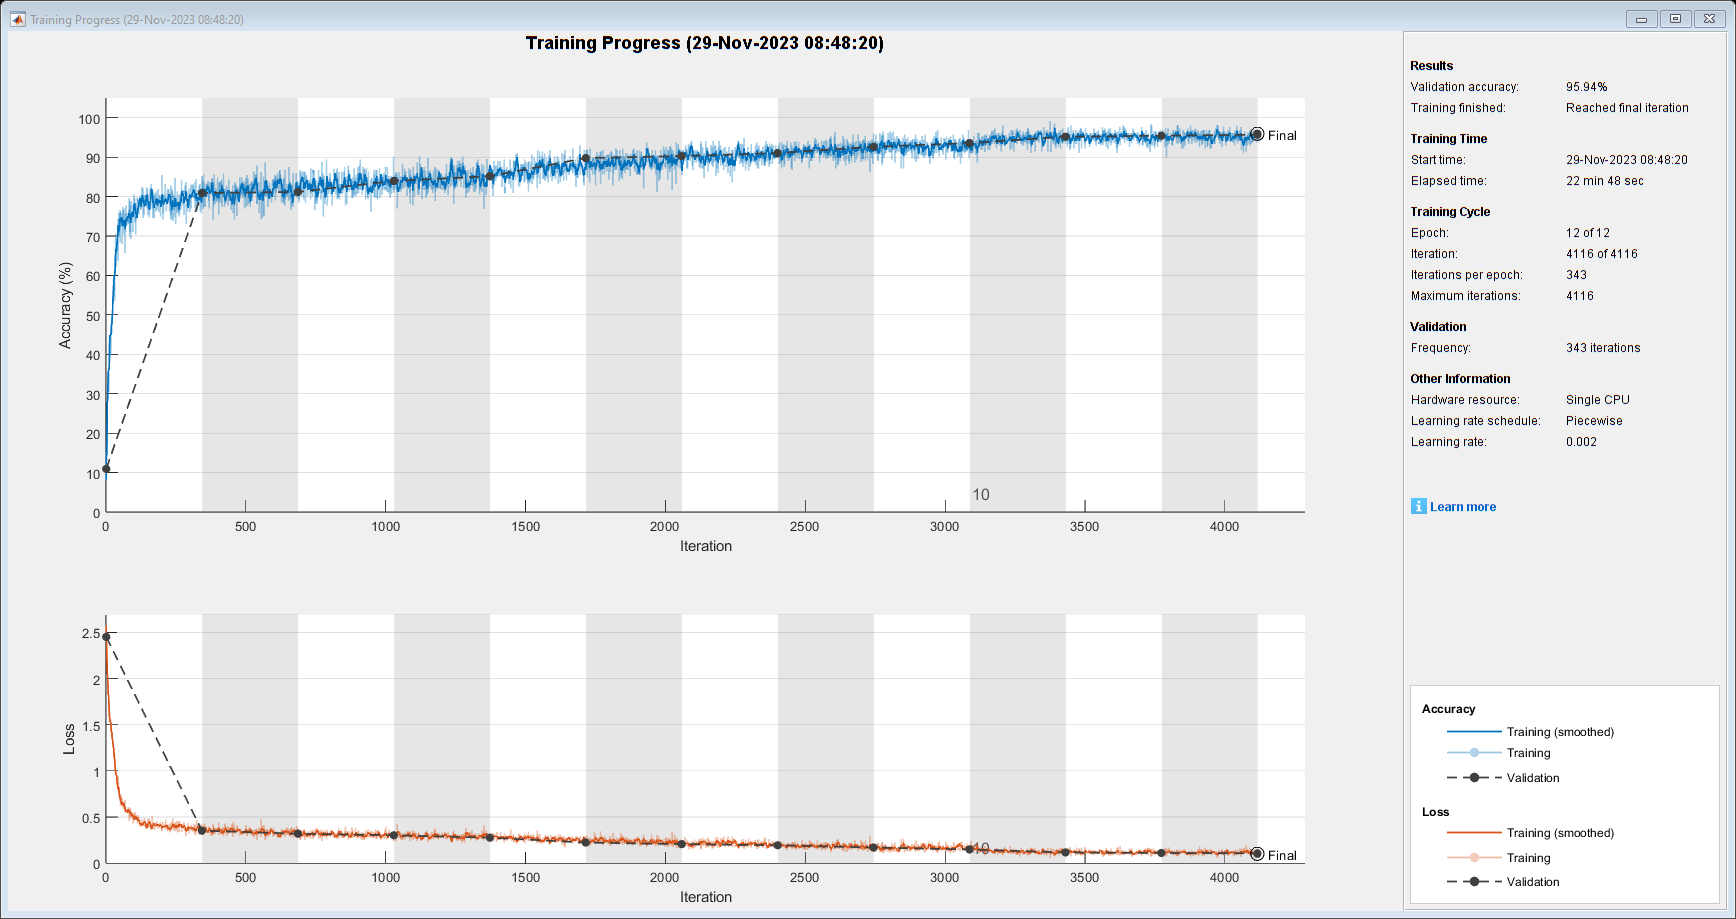

  trainedNet = trainNetwork(rxTrainFrames,rxTrainLabels,modClassNet,options);

fprintf('%s - Classifying test frames\n', datestr(toc/86400,'HH:MM:SS'))

00:37:50 - Classifying test frames


% Gather the test frames into the memory
testFramesTall = tall(transform(testDSTrans, @helperModClassReadFrame));
rxTestFrames = gather(testFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 13 sec
Evaluation completed in 13 sec


rxTestFrames = cat(4, rxTestFrames{:});

% Gather the test labels into the memory
testLabelsTall = tall(transform(testDSTrans, @helperModClassReadLabel));
rxTestLabels = gather(testLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 12 sec
- Pass 2 of 2: Completed in 14 sec
Evaluation completed in 26 sec


rxTestPred = classify(trainedNet,rxTestFrames);
testAccuracy = mean(rxTestPred == rxTestLabels);
disp("Test accuracy: " + testAccuracy*100 + "%")

Test accuracy: 95.9364%


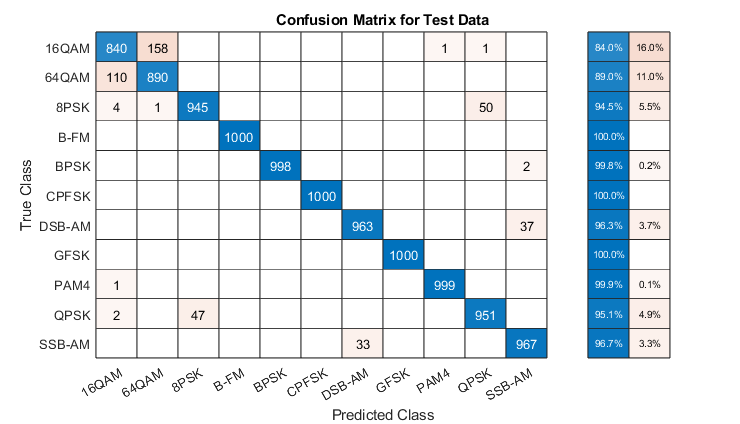

figure
cm = confusionchart(rxTestLabels, rxTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 740 424];

## **Predict Modulation Type Using CNN**

load trainedModulationClassificationNetwork
trainedNet

trainedNet =   SeriesNetwork with properties:

         Layers: [28×1 nnet.cnn.layer.Layer]
     InputNames: {'Input Layer'}
    OutputNames: {'Output'}


% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(123456)
% Random bits
d = randi([0 3], 1024, 1);
% PAM4 modulation
syms = pammod(d,4);
% Square-root raised cosine filter
filterCoeffs = rcosdesign(0.35,4,8);
tx = filter(filterCoeffs,1,upsample(syms,8));

% Channel
SNR = 30;
maxOffset = 5;
fc = 902e6;
fs = 200e3;
multipathChannel = comm.RicianChannel(...
  'SampleRate', fs, ...
  'PathDelays', [0 1.8 3.4] / 200e3, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4);

frequencyShifter = comm.PhaseFrequencyOffset(...
  'SampleRate', fs);

% Apply an independent multipath channel
reset(multipathChannel)
outMultipathChan = multipathChannel(tx);

% Determine clock offset factor
clockOffset = (rand() * 2*maxOffset) - maxOffset;
C = 1 + clockOffset / 1e6;

% Add frequency offset
frequencyShifter.FrequencyOffset = -(C-1)*fc;
outFreqShifter = frequencyShifter(outMultipathChan);

% Add sampling time drift
t = (0:length(tx)-1)' / fs;
newFs = fs * C;
tp = (0:length(tx)-1)' / newFs;
outTimeDrift = interp1(t, outFreqShifter, tp);

% Add noise
rx = awgn(outTimeDrift,SNR,0);

% Frame generation for classification
unknownFrames = helperModClassGetNNFrames(rx);

% Classification
[prediction1,score1] = classify(trainedNet,unknownFrames)

prediction1 = 7×1 categorical array
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 


score1 = 7×11 single matrix
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0007    0.0000    0.0000    0.0000    0.9993    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.9999    0.0000    0.0000


prediction1

prediction1 = 7×1 categorical array
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 
     PAM4 


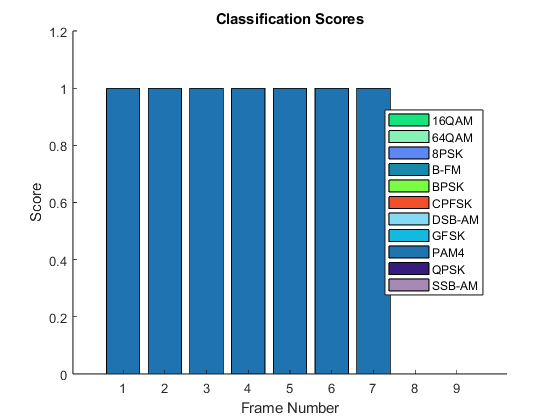

helperModClassPlotScores(score1,modulationTypes)